% Simon Yoon
% ECE300PS07 Q2 

clc
clear
close all;

## Filter Design

beta = 0.3; % rolloff factor
span = 4; % number of symbols
L = 16; % samples per symbol
Rs = 10e5; % bits per second

p = rcosdesign(beta, span, L, 'sqrt');

% g
g = conv(p,fliplr(p));
leng = size(g,1);
x1 = 0:length(p)-1; % graph support
x2 = 0:length(g)-1;

## Impulse Response

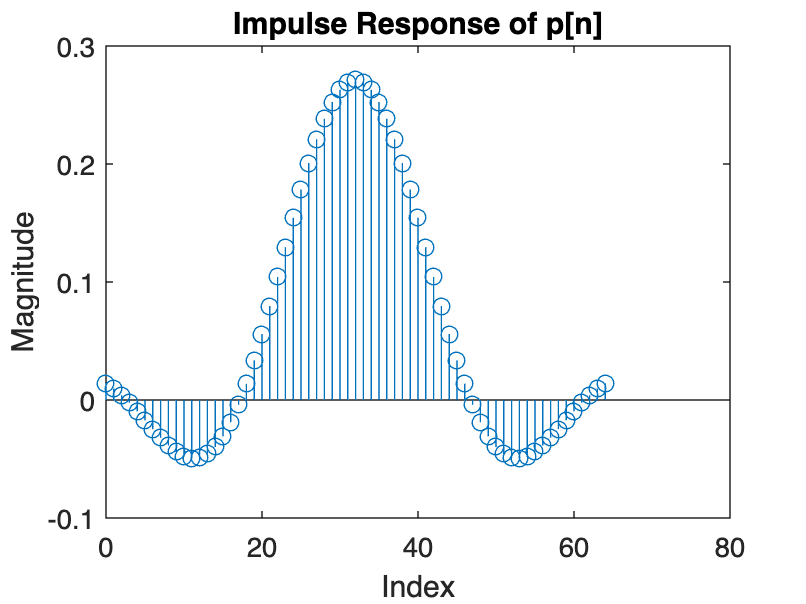

% p
figure(1);
stem(x1, p);
ylim([-0.1 0.3])
xlabel("Index")
ylabel("Magnitude")
title("Impulse Response of p[n]")

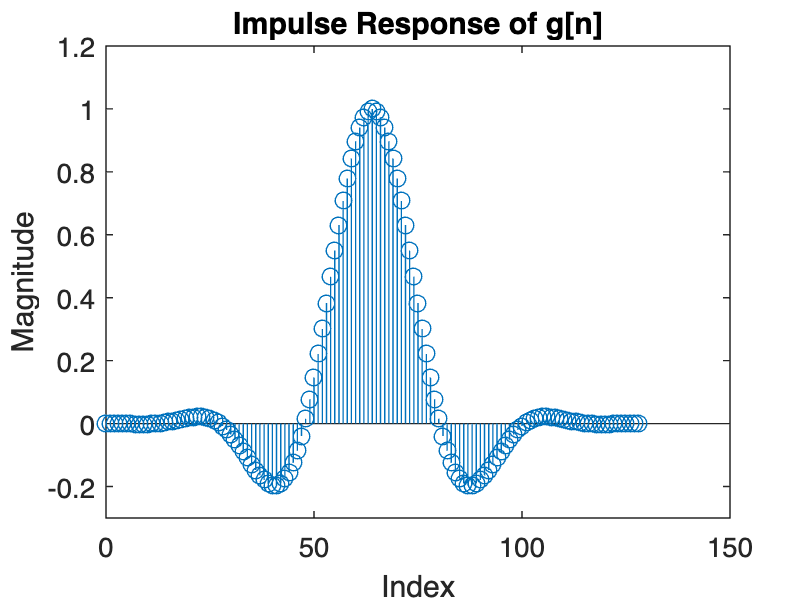


% g
figure(2);
stem(x2, g);
ylim([-0.3 1.2]);
xlabel("Index")
ylabel("Magnitude")
title("Impulse Response of g[n]")

## Peaks & Maximum Magnitude of Single Interferer

% P
[Mp, ip] = max(p);
fprintf("kp_peak : %f at p[%d] \n", Mp, ip-1);

kp_peak : 0.271386 at p[32] 



% G and Single Interferer Magnitude
[Mg, ig] = max(g);
% or use maxg = find(g==1); b/c "the peak value of g is 1".
fprintf("kg_peak : %f at g[%d] \n", Mg, ig-1);

kg_peak : 1.000000 at g[64] 


fprintf("Maximum magnitude of any single interferer : %f \n", g(65 + L));

Maximum magnitude of any single interferer : 0.015283 


## ISI & SIR

n = find(g==1);
i= n:8:leng;
i = i(2:end); 
j = n:-8:1;
j = j(2:end); 
j = flip(j,2);
i = [j i]; % indices of ISI values
ISI = sqrt(2)*sum(abs(g(i)));

sigp = 1; % BPSK: symbols -> 1
SIR = 10*log10(sigp/ISI^2);
fprintf("Signal-to-interference ratio (SIR) : %f dB \n", SIR);

Signal-to-interference ratio (SIR) : -2.480118 dB 


## Magnitude Spectras

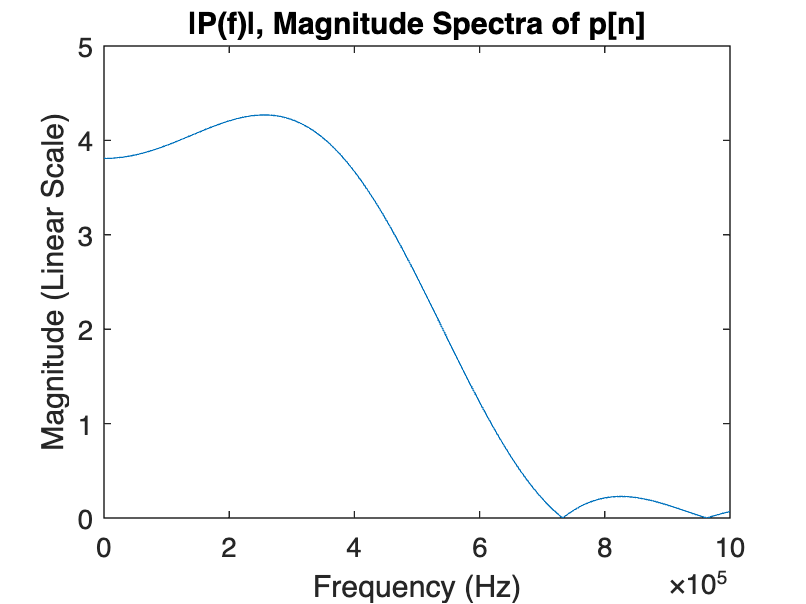

f = linspace(0, Rs, 1000); % @ 1000 frequency pts
[H, w] = freqz(p, 1, f, Rs*L);
[Hg, wg] = freqz(g, 1, f, Rs*L);
Hgf = fliplr(Hg);

figure(3);
plot(w, abs(H));
xlabel("Frequency (Hz)");
ylabel("Magnitude (Linear Scale)");
title("|P(f)|, Magnitude Spectra of p[n]");

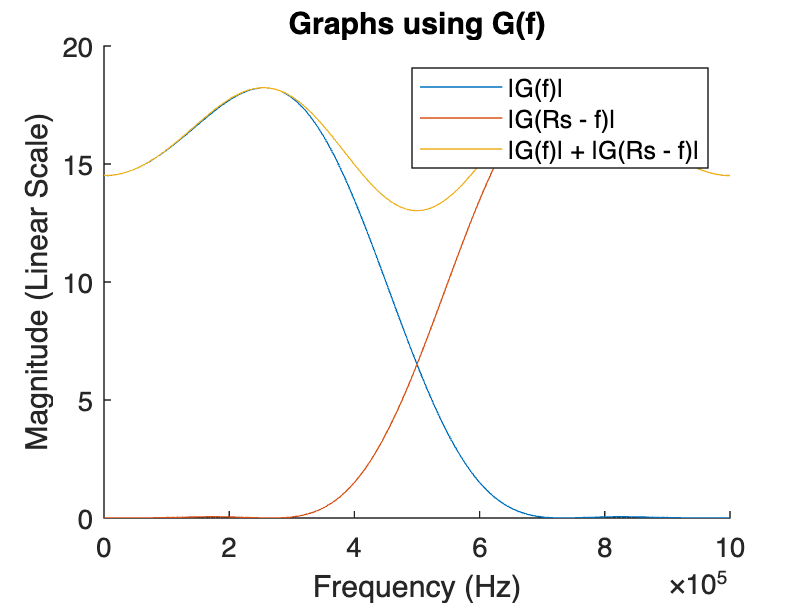


figure(4);
hold on;
plot(wg, abs(Hg));
plot(wg, abs(Hgf));
plot(wg, abs(Hg) + abs(Hgf));
xlabel("Frequency (Hz)");
ylabel("Magnitude (Linear Scale)");
title("Graphs using G(f)");
legend("|G(f)|", "|G(Rs - f)|", "|G(f)| + |G(Rs - f)|")

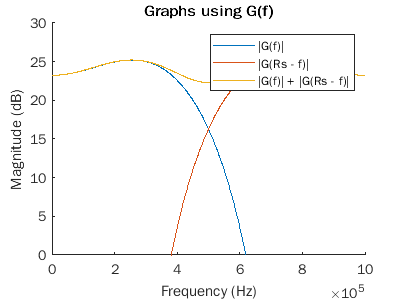


figure(5);
hold on;
plot(wg, 20*log10(abs(Hg)));
plot(wg, 20*log10(abs(Hgf)));
plot(wg, 20*log10(abs(Hg) + abs(Hgf)));
ylim([0, 30])
xlabel("Frequency (Hz)");
ylabel("Magnitude (dB)");
title("Graphs using G(f)");
legend("|G(f)|", "|G(Rs - f)|", "|G(f)| + |G(Rs - f)|")